# Revision del dataset Iris paso a paso

Cada seccion deja una tabla en el workspace: T0_crudo, T1_outliers, T2_balanceado, T3_estandarizado y T4_normalizado. R3 entrena el perceptron y el Adaline sobre cada una.

clear; close all; clc

## Paso 0: dato crudo

iris = load('iris.dat');
T = array2table(iris(:,1:4), 'VariableNames', {'largo_sepalo','ancho_sepalo','largo_petalo','ancho_petalo'});
T.clase = categorical(iris(:,5), 1:3, {'setosa','versicolor','virginica'});
vars = T.Properties.VariableNames(1:4);
T0_crudo = T;
summary(T0_crudo)


T0_crudo: 150×5 table

Variables:

    largo_sepalo: double
    ancho_sepalo: double
    largo_petalo: double
    ancho_petalo: double
    clase: categorical (3 categories)

Statistics for applicable variables:

                    NumMissing       Min          Median         Max           Mean          Std    

    largo_sepalo        0           4.3000        5.8000        7.9000        5.8433        0.8281  
    ancho_sepalo        0                2             3        4.4000        3.0573        0.4359  
    largo_petalo        0                1        4.3500        6.9000        3.7580        1.7653  
    ancho_petalo        0           0.1000        1.3000        2.5000        1.1993        0.7622  
    clase               0                                                                           



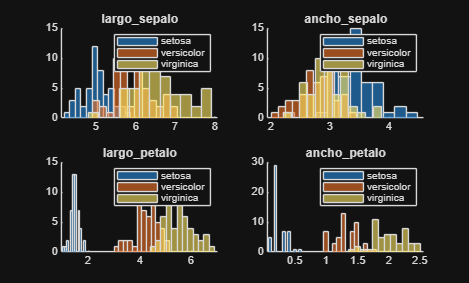


figure
for k = 1:4
    subplot(2,2,k); hold on
    for c = categories(T.clase)'
        histogram(T.(vars{k})(T.clase == c{1}), 12, 'DisplayName', c{1})
    end
    title(vars{k}, 'Interpreter', 'none'); legend
end

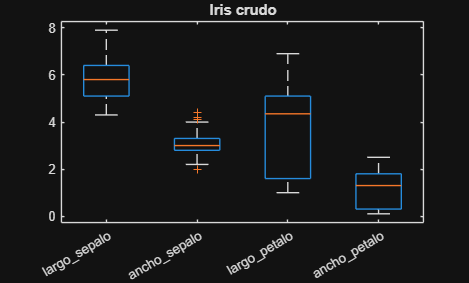


figure
boxplot(T{:,vars}, 'Labels', vars); title('Iris crudo')

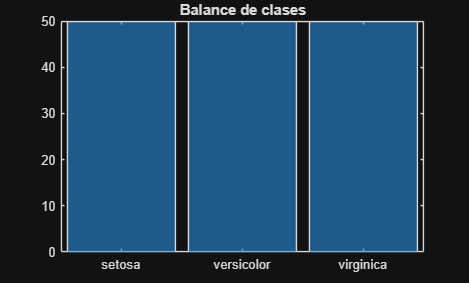


figure
histogram(T.clase); title('Balance de clases')

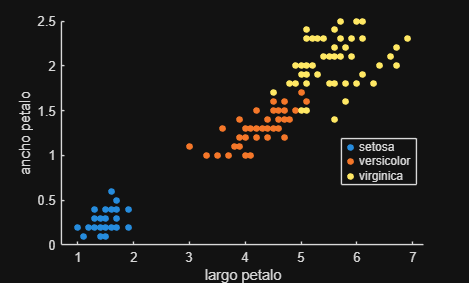


figure
gscatter(T.largo_petalo, T.ancho_petalo, T.clase)
xlabel('largo petalo'); ylabel('ancho petalo')

## Paso 1: outliers con la regla 1.5*IQR, recortando al borde

T1_outliers = T0_crudo;
for k = 1:4
    x = T1_outliers.(vars{k});
    q = quantile(x, [0.25 0.75]);
    li = q(1) - 1.5*(q(2)-q(1));  ls = q(2) + 1.5*(q(2)-q(1));
    fuera(k) = sum(x < li | x > ls);
    x(x < li) = li;  x(x > ls) = ls;
    T1_outliers.(vars{k}) = x;
end
fuera

fuera =      0     4     0     0


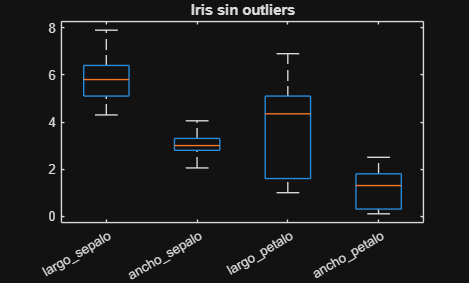

figure
boxplot(T1_outliers{:,vars}, 'Labels', vars); title('Iris sin outliers')

## Paso 2: balanceo

Iris ya viene con 50 de cada clase, no hay nada que hacer

T2_balanceado = T1_outliers;
countcats(T2_balanceado.clase)'

ans =     50    50    50


## Paso 3: estandarizar

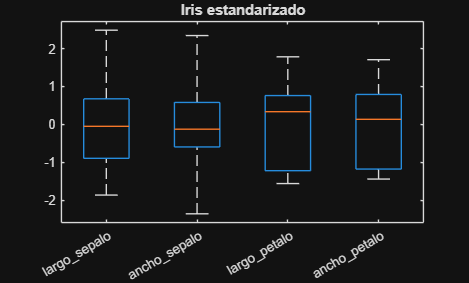

T3_estandarizado = T2_balanceado;
T3_estandarizado{:,vars} = zscore(T2_balanceado{:,vars});
figure
boxplot(T3_estandarizado{:,vars}, 'Labels', vars); title('Iris estandarizado')

## Paso 4: normalizar entre 0 y 1 (parte del balanceado, no del estandarizado)

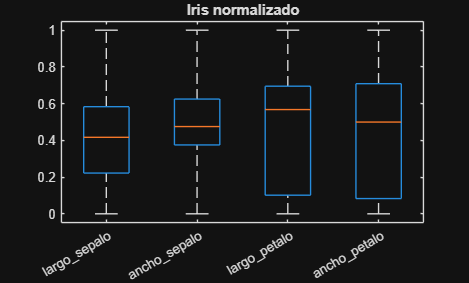

T4_normalizado = T2_balanceado;
T4_normalizado{:,vars} = normalize(T2_balanceado{:,vars}, 'range');
figure
boxplot(T4_normalizado{:,vars}, 'Labels', vars); title('Iris normalizado')


save('iris_pasos.mat', 'T0_crudo', 'T1_outliers', 'T2_balanceado', 'T3_estandarizado', 'T4_normalizado')